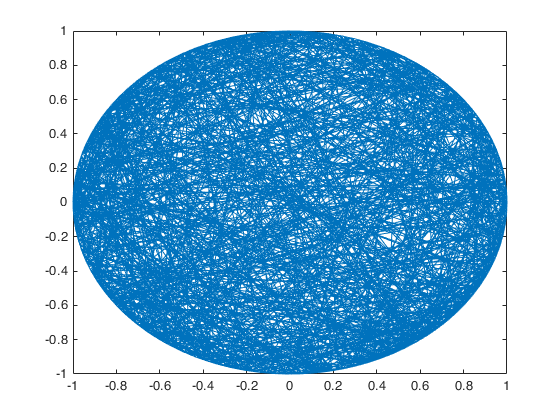

clear
%Código para dibujar la circunferencia y dibujar sobre ella las iteraciones
ang = linspace(0,2*pi) ;
plot(cos(ang),sin(ang))
hold on
%Contador para evaluar si el punto está en la circunferencia
i=0 ;
%Contador para evaluar si la longitud de la cuerda es mayor que raíz de 3
j=0 ;
%Bucle para simular las 1000 cuerdas
while i < 1000
    %Selección aleatoria uniforme de dos puntos (1, alpha), (1, beta)
    alpha = 2*pi*rand(1,1) ;
    beta = 2*pi*rand(1,1) ;
    %Cuerda generada entre los dos puntos
    line([cos(alpha), cos(beta)],[sin(alpha), sin(beta)])
    %Aumento del contador
    i = i + 1 ;
    %Condicional para determinar si la longitud de la cuerda generada es mayor que raíz de 3
    if  sqrt((cos(alpha)-cos(beta))^2+(sin(alpha)-sin(beta))^2) > sqrt(3)
        %Aumento del contador
        j = j + 1 ;
    end
end

%Cantidad de cuerdas con longitud mayor que raíz de 3
j

j = 334

%Porcentaje de j
j/i

ans = 0.3340